%calculating the mean first passage time analytically/numerically 
%to investigate effect of multiple invader-substrate on RNA/DNA TMSD
%kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 4 %define invader toehold length 

g = 4

m = zeros(1, 4)

m =      0     0     0     0


m(1) = 0 %define position of first mismatch

m =      0     0     0     0



R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.8*R*temp

dGrd = -0.4739

dGmm = 9.5*R*temp

dGmm = 5.6280

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(4,19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(4, 19)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(4, 19)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(4, 19)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(4, 19)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(4, 19)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through number of mismatches
for ind = 2:5 
    %loop through mismatch position
    for pos = m(ind-1)+1:b-1
        m(ind) = pos
        
        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_bp * exp(dGbp/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Crm = k_bp * exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added + dGrd
        k_CD = k_bp * exp(-dGbm/(R*temp));
        k_DC = 0 
        k_DD = 1
        
        %create arrays of forward and reverse transition rates for
        %mismatch-free system
        Kf_perf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb_perf = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
        for no = 1:ind
            if m(no) ~= 0 
                Kb(b - m(no) + 1) = k_Crm
            end
        end
            
        %define spontaneous incumbent dissociation rate
        Koff = [0]; 
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state for mismatch system
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        
        Pn_jN_1_perf = zeros(1,numel(Kf_perf))
        jn_jN_1_perf = zeros(1,numel(Kf_perf))
        Pn_jN_1_perf (1) = 0;
        jn_jN_1_perf (1) = 1;
        
        %calculate flux between each state for mismatch-free system
        for Pn = 2:numel(Kf_perf)
            Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
            jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
        end
    
        first_pass_time (ind-1, pos) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
        k_eff (ind-1, pos) = 1/(first_pass_time (ind-1, pos)*(5*10^-8)); %effective rate constant for mismatch system
        prob_unbound(ind-1, pos) = Pn_jN_1(end)/sum(Pn_jN_1) %prob of being in unbound state for mismatch system
        
        first_pass_time_perf (ind-1, pos) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
        k_eff_perf (ind-1, pos) = 1/(first_pass_time_perf (ind-1, pos)*(5*10^-8)); %effective rate constant for mismatch-free system
        prob_unbound_perf(ind-1, pos) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for mismatch-free system
    end
    m(ind) = m(ind-1) + 3; %introduce space between mismatches
end

m =      0     1     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb = 	1.0e+08 *

         0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0195    0.0195    0.0195    0.0195         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    5.5783         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     2     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb = 	1.0e+08 *

         0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    5.5783    2.5102         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb = 	1.0e+08 *

         0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    5.5783    2.5102    1.1316         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     4     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     5     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     6     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     7     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     8     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     9     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    10     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    11     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    12     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    13     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    14     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    15     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066    0.0062         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    16     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066    0.0062    0.0061         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    17     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066    0.0062    0.0061    0.0061         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    18     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066    0.0062    0.0061    0.0061    0.0061         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0    19     0     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.5783    2.5102    1.1316    0.5121    0.2338    0.1087    0.0525    0.0273    0.0159    0.0108    0.0086    0.0075    0.0070    0.0066    0.0062    0.0061    0.0061    0.0061    0.0061
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     4     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     5     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     7     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     8     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     9     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    10     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    11     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    12     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    13     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    14     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    15     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027    0.0013         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    16     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027    0.0013    0.0011         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    17     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027    0.0013    0.0011    0.0011         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    18     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027    0.0013    0.0011    0.0011    0.0011         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3    19     0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0056    0.0025    0.0011    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    6.7571    3.0367    1.3650    0.6139    0.2764    0.1247    0.0566    0.0259    0.0122    0.0059    0.0027    0.0013    0.0011    0.0011    0.0011    0.0011
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6     7


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6     8


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6     9


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    10


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    11


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    12


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    13


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    14


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    15


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217    0.0035         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    16


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217    0.0035    0.0015         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    17


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217    0.0035    0.0015    0.0014         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    18


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217    0.0035    0.0015    0.0014    0.0014         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6    19


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0068    0.0030    0.0014    0.0006    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    8.1872    3.6782    1.6522    0.7418    0.3327    0.1486    0.0644    0.0217    0.0035    0.0015    0.0014    0.0014    0.0014
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      0     3     6     9    10


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995         0         0         0         0         0         0         0         0         0


m =      0     3     6     9    11


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957         0         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995         0         0         0         0         0         0         0         0


m =      0     3     6     9    12


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622         0         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973         0         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028         0         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995         0         0         0         0         0         0         0


m =      0     3     6     9    13


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427         0         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0


m =      0     3     6     9    14


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733         0         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0


m =      0     3     6     9    15


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733    0.0308         0         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0


m =      0     3     6     9    16


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733    0.0308    0.0029         0         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0


m =      0     3     6     9    17


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733    0.0308    0.0029    0.0017         0         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0


m =      0     3     6     9    18


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733    0.0308    0.0029    0.0017    0.0017         0


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973         0


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028         0


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0


m =      0     3     6     9    19


k_AB1 = 0.2005

k_B1A = 1.9523e+06

ans = 4.3448e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_Crm = 1.9814e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Kb =          0    1.9814    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    1.9814    0.0001    0.0001    0.0195    0.0195    0.0195    0.0195         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0    0.0082    0.0037    0.0017    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0    9.7329    4.3957    1.9622    0.8427    0.2733    0.0308    0.0029    0.0017    0.0017    0.0017


prob_unbound =     0.9978    0.9976    0.9973    0.9967    0.9953    0.9924    0.9867    0.9763    0.9610    0.9438    0.9296    0.9210    0.9195    0.9387    0.9840    0.9980    0.9994    0.9995    0.9995
         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9972    0.9972    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
         0         0         0         0         0         0         0         0         0    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973


first_pass_time_perf =     6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028
         0         0         0         0         0         0         0         0         0    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028    6.1028


prob_unbound_perf =     0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995
         0         0         0         0         0         0         0         0         0    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995


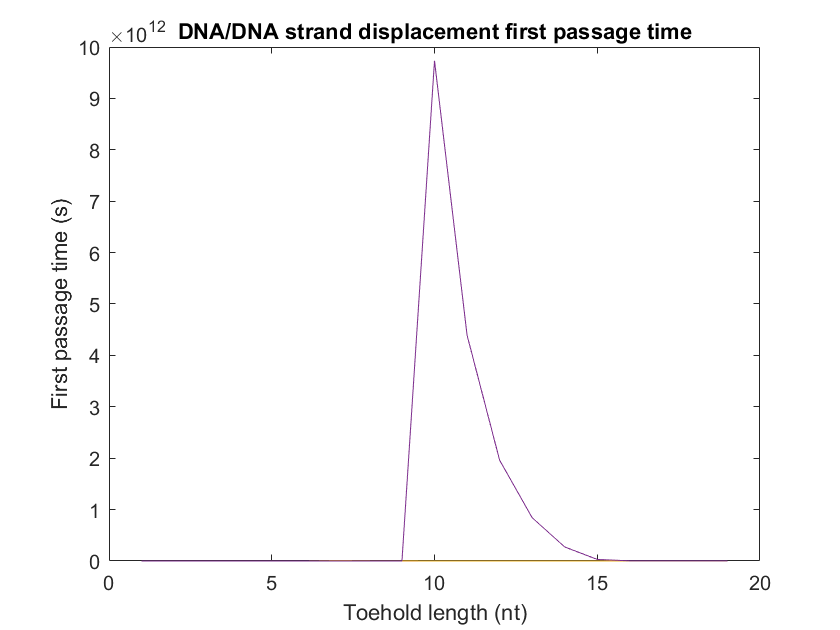

plot(1:19, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

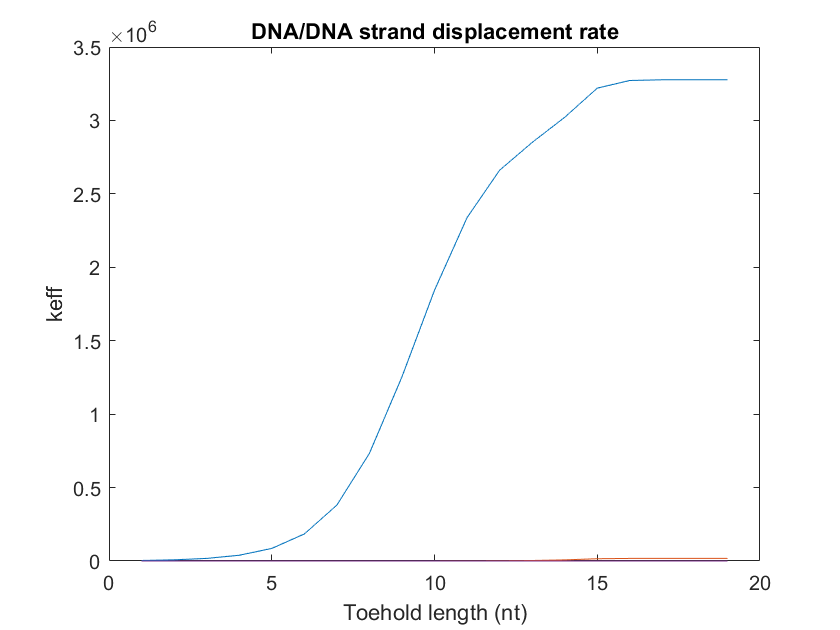


plot(1:19, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

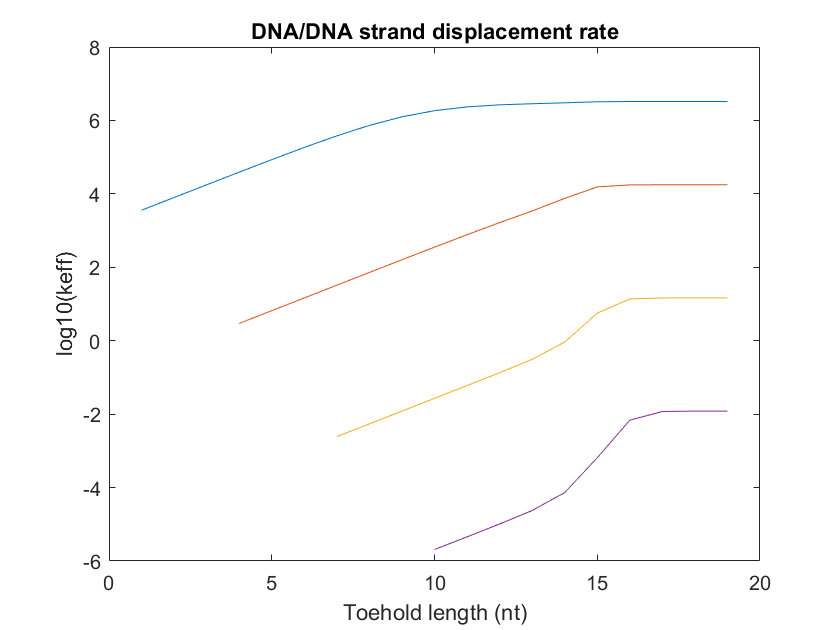


plot(1:19, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  

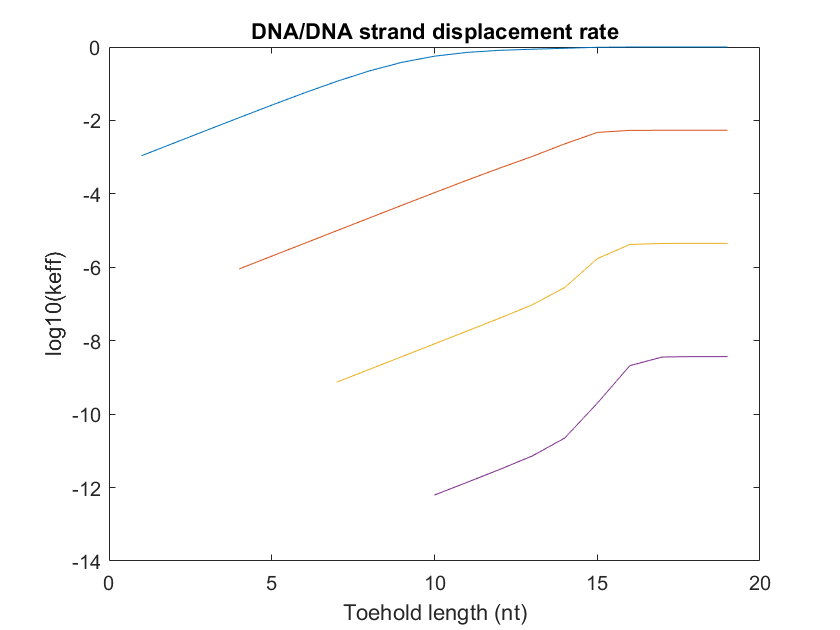


plot(1:19, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  